Basins of attraction

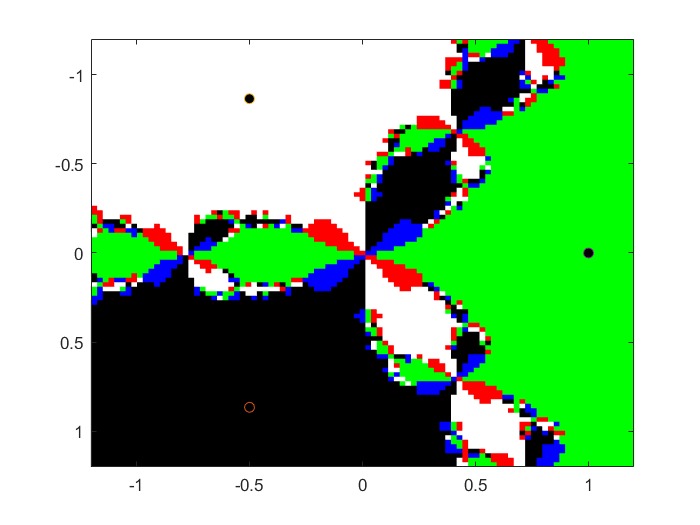

clear
tol = 1e-100;
M = 1000;
n = 100;
x = linspace(-1.25, 1.25, n);
y = linspace(-1.25, 1.25, n);
K = ones(n, 1)*x + 1i*y'*ones(1, n);% n*n matrix
K0 = K;

% Functions
fz = [1 0 0 -1];    % f(z)
fdz = polyder(fz);  % f'(z)
fd = polyval(fdz, K);

% Function handles
fh = @(z) z.^3 - 1;  % f(z)
fhd = @(z) 3*z.^2;   % f'(z)  

Kf = fh(K);
Kfd = fhd(K);

r = roots(fz);
rn = length(r);
%M = cell(1, rn);
for i = 1:M
    K = K - polyval(fz, K)./polyval(fdz, K);    %K = K - fh(K)./fhd(K);
    
    for j = 1: rn
        Mat{j} = abs(K - r(j));
        MinMat(j) = min(Mat{1,j}(:));
    end

    if min(MinMat(:)) < tol
        iter = i;
        break;
    end
    if i == M
        iter = M;
    end
end

[raw, col] = find(abs(K - r(1)) > tol & abs(K - r(2)) > tol & abs(K - r(3)) > tol) ;
for i = 1: length(raw);
    diverge(i) = K0(raw(i), col(i));
end
Diverge = unique(diverge(:));

hold on
h = pcolor(x, y, angle(K));
h.EdgeColor = 'none';
plot(real(r(1)), imag(r(1)), 'o', 'MarkerFaceColor', 'black')
plot(real(r(2)), imag(r(2)), 'o', 'MarkerFaceColor', 'black')
plot(real(r(3)), imag(r(3)), 'o', 'MarkerFaceColor', 'black')
%plot(real(Diverge), imag(Diverge));
hold off

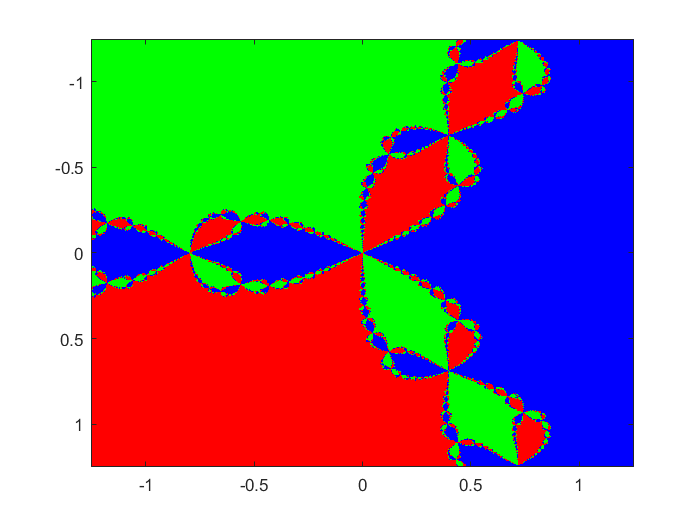

clear
tol = 1e-6;
M = 200;
n = 1000;
x = linspace(-1.25, 1.25, n);
y = linspace(-1.25, 1.25, n);

% Functions
fz = [1 0 0 -1];    % f(z)
fdz = polyder(fz);  % f'(z)


K = zeros(length(x), length(y));
K1 = zeros(size(K));
K2 = zeros(size(K));
K3 = zeros(size(K));
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;
r = roots(fz);
rn = length(r);
fd = polyval(fdz, Z);

for k = 1:M
    Z = Z - polyval(fz, Z)./polyval(fdz, Z);    %K = K - fh(K)./fhd(K);
    K1(abs(Z-r(1)) < tol) = k;
    K2(abs(Z-r(2)) < tol) = k;
    K3(abs(Z-r(3)) < tol) = k;
%     if max(K1(:))
%         break;
%     elseif max(K2(:))  
%         break;
%     elseif max(K3(:))      
%         break;
%     end
end
K(:,:,1) = K1;
K(:,:,2) = K2;
K(:,:,3) = K3;
image(x, y, K)

p = [1 0 0 -1];
np = length(p) - 1;
dp = polyder(p);
r = roots(p);
tol = 1e-1;
M = 1000;
x = linspace(-1.2, 1.2, 1000);
y = linspace(-1.2, 1.2, 1000);
C = zeros(length(y), length(x), 'uint8');
cmap = [1 1 1; 1 0 0; 0 1 0; 0 0 1; 0 0 0];
[X, Y] = meshgrid(x, y);
Z = X + 1i*Y;
depth = 100;
tic
for j = 1:depth
    Z = Z - polyval(p, Z)./(polyval(dp, Z) + eps); % To avoid division by zero
    for k = 1:np
        C(abs(Z - r(k)) < tol) = k;
    end
    C(abs(Z) > M) = np + 1;
end
toc

Elapsed time is 7.815562 seconds.


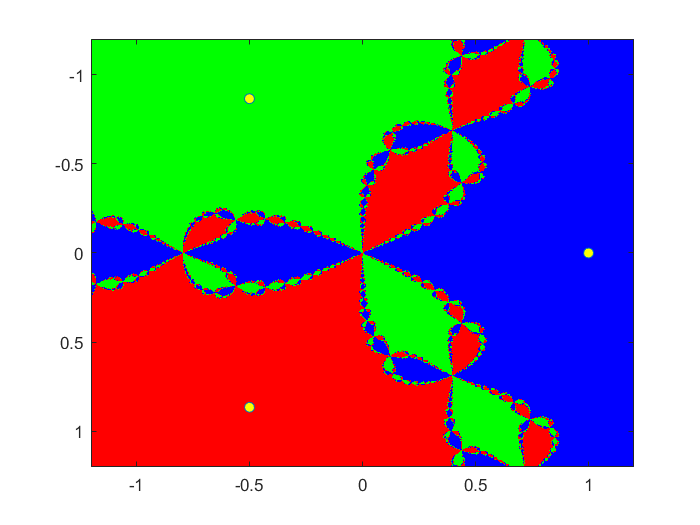

image(x, y, C);
colormap(cmap);
hold on
plot(r, 'o', 'MarkerFaceColor', 'y')
hold off